# Support Vector Machines

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

Use the whole dataset (without splitting) to train a standard Support Vector Machine (SVM) and visualise its linear decision boundary. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset using default hyperparameters [2 marks]

- Generating a "grid" of testing data which spans the minimum and maximum value of each feature in the training dataset [8 marks]

- Using your trained SVM to classifiy the testing data you have generated [2 marks]

- Generating a scatter plot of your testing data, with each point colour-coded by the associated classification result [2 marks]

- Superimposing the original training data so that it is clearly visible [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
examples

examples = 100×2 table
    sepal_width    sepal_length
    ___________    ____________

      0.98572          1.1134  
      0.98572          0.2082  
       0.6852         0.96253  
       -1.719         -1.1496  
     -0.21638         0.35906  
     -0.21638        -0.84787  
       1.2862         0.05733  
      -1.4185         -2.0548  
     0.084147         0.50993  
      -0.5169         -1.6022  
      -2.6206         -1.9039  
      0.38467        -0.54614  
      -2.0195        -0.39527  
     0.084147         -0.2444  
     0.084147        -0.99874  
       0.6852          0.6608  


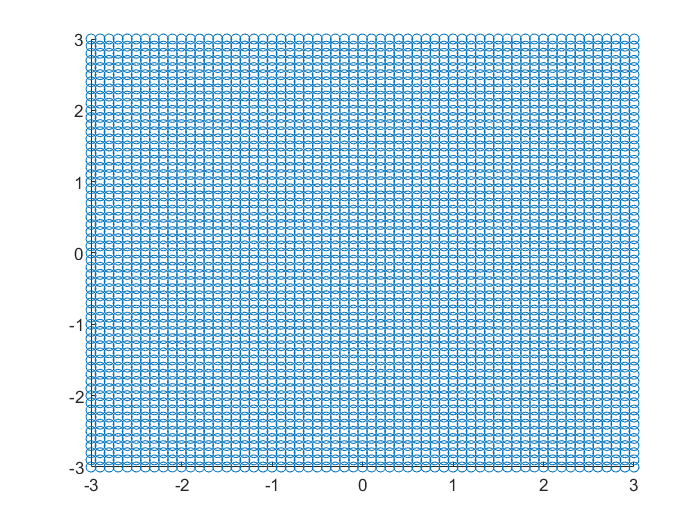

a =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×3721 double]
              YData: [1×3721 double]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


%m = fitcsvm(examples, labels)
m = fitcsvm(examples, labels);
i = [];
j = [];
% using a nested for loop to generate a grid of information
% -3 and 3 where selected as the min and max values as reviewing the examples table not number was higher or lower than them
% implemented intervals of 0.1 to go up in
for x = -3:0.1:3
    for y = -3:0.1:3
        
             i = [i;y];
             j = [j;x];
    end
end
% displays all of the values from the example table within a scatter graph
a = scatter(i,j)

q = [i,j];

% the scatter graph was then colour coded depending on wether a value was
% an versicolor or virginicia, the information was then displayed within a
% group scatter graph
[label, score] = predict(m,q)

label = 3721×1 categorical array
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor

score =     4.0231   -4.0231
    3.9965   -3.9965
    3.9699   -3.9699
    3.9433   -3.9433
    3.9167   -3.9167
    3.8901   -3.8901
    3.8635   -3.8635
    3.8369   -3.8369
    3.8103   -3.8103
    3.7837   -3.7837


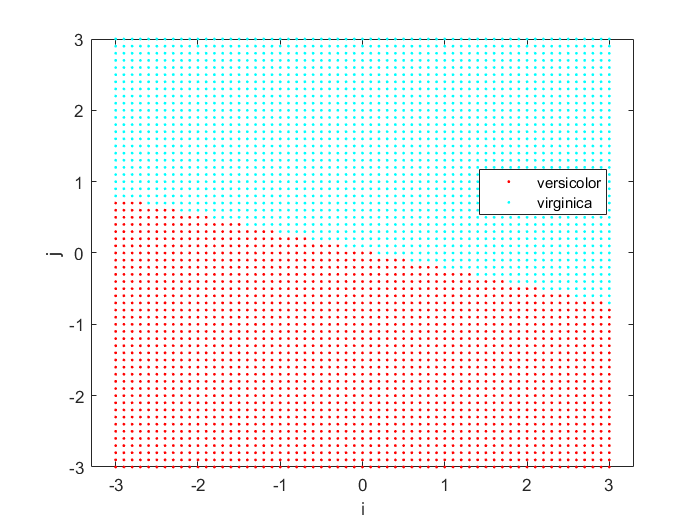

gscatter(i, j, label)


% superimposing the original traing data onto the the testing data to
% clearly show the difference in data
% assigning two new values to equal example adn plotting them over the
% previous graph

a = examples{:,1};
b = examples{:,2};
g = [a, b]

g =     0.9857    1.1134
    0.9857    0.2082
    0.6852    0.9625
   -1.7190   -1.1496
   -0.2164    0.3591
   -0.2164   -0.8479
    1.2862    0.0573
   -1.4185   -2.0548
    0.0841    0.5099
   -0.5169   -1.6022


[label1,score] = predict(m,g)

label1 = 100×1 categorical array
     virginica 
     virginica 
     virginica 
     versicolor 
     virginica 
     versicolor 
     virginica 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     virginica 
     virginica 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     versicolor 
     virginica 
     versicolor 
     virginica 
     virginica 
     virginica 
     virginica 
     versicolor 
     virginica 

score =    -1.3999    1.3999
   -0.4398    0.4398
   -1.1600    1.1600
    1.7197   -1.7197
   -0.2801    0.2801
    1.0001   -1.0001
   -0.3597    0.3597
    2.5999   -2.5999
   -0.5201    0.5201
    1.8801   -1.8801


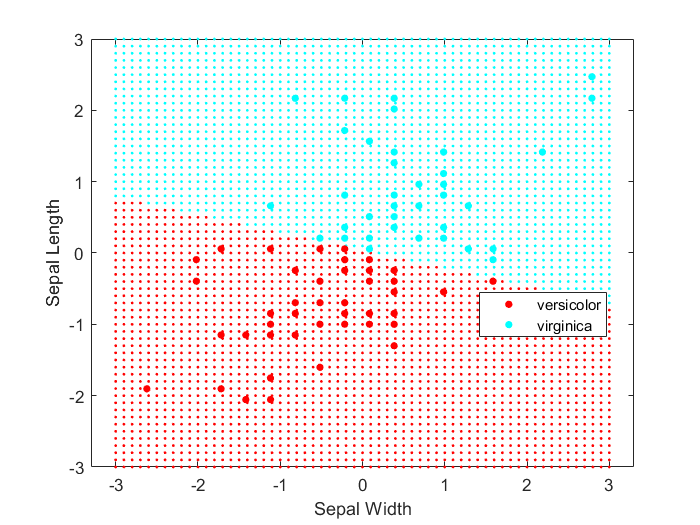


%
gscatter(i, j, label)
hold on
gscatter(a, b, label1)

xlabel('Sepal Width')
ylabel('Sepal Length')